# 第七章 交互式仿真工具Simulink

## 1. Simulink建模仿真的基本操作过程：使用simulink设计一个简单的模型，将正弦信号输出到示波器，仿真时间0-200。

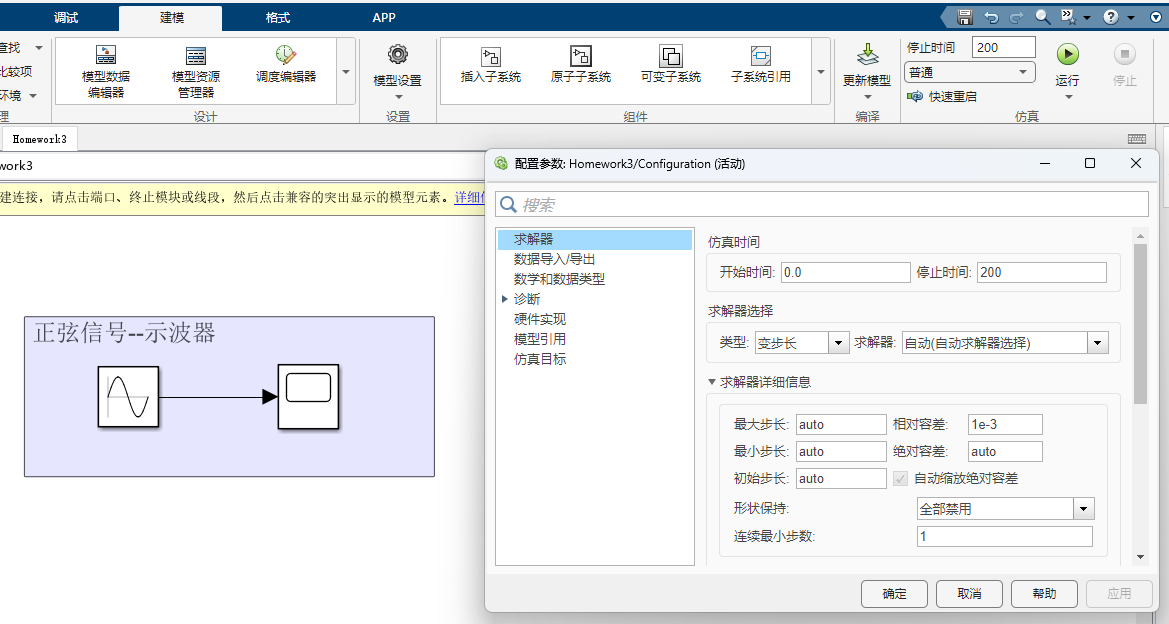

## 2.使用下面给出的模块，自由组合练习。随机选取3种考查是否掌握了使用方法。

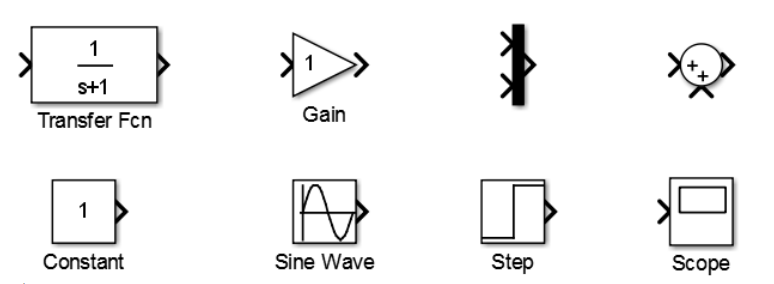

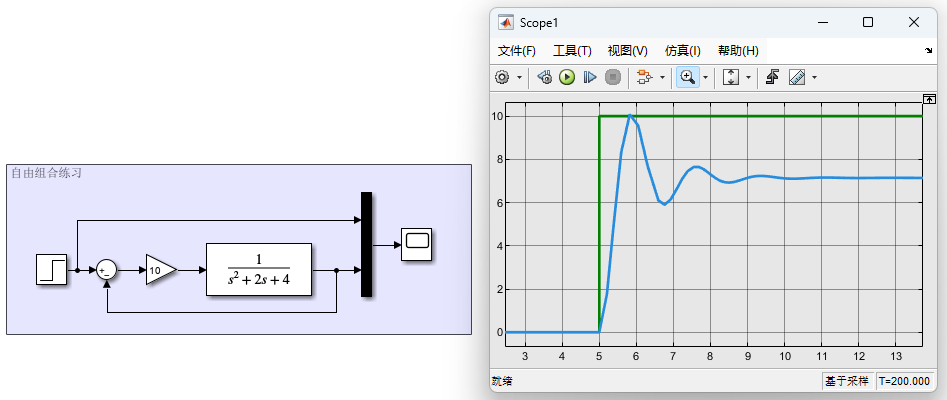

## 3.已知单轴机械臂控制系统框图如下所示，使用Simulink给出其阶越响应曲线。其中：放大器取值范围Ka=10-1000；G(s)=1/s^3+1020s^2+2000s。

## 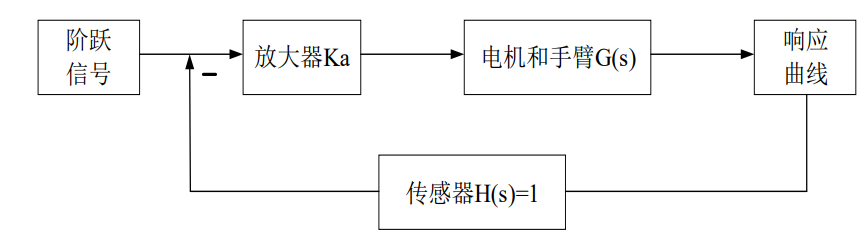

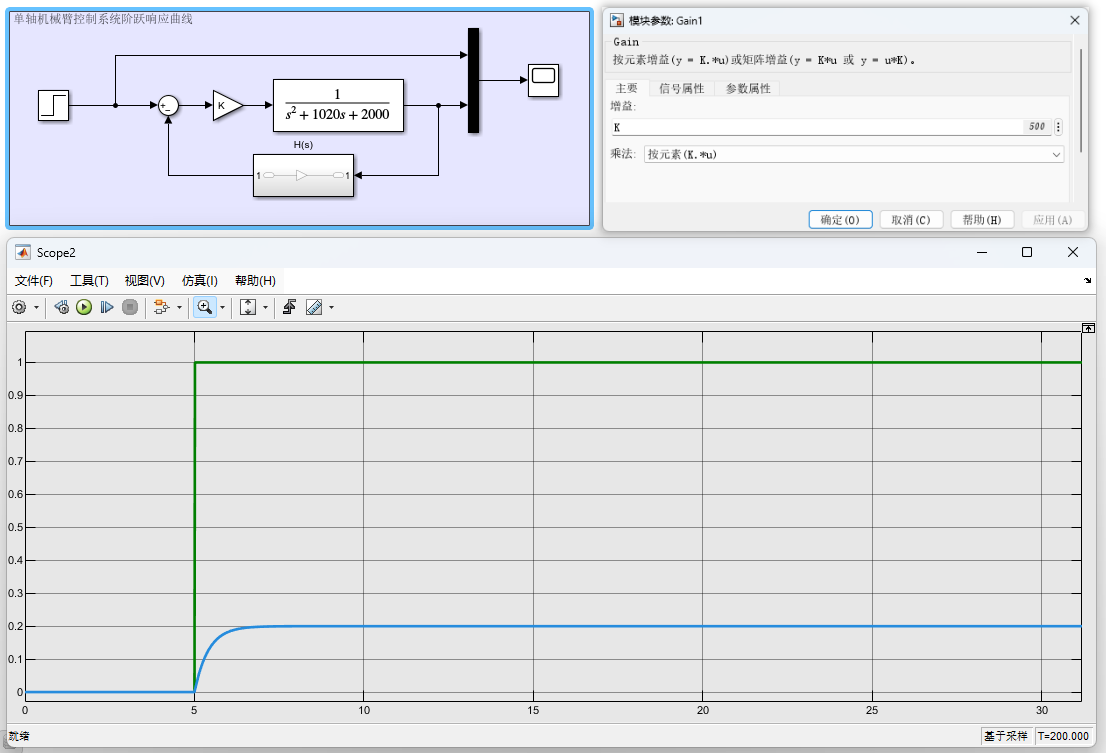

# 第8章 控制系统模型的定义

## 1. 已知系统的零极点模型如下，试用MATLAB进行描述并封装

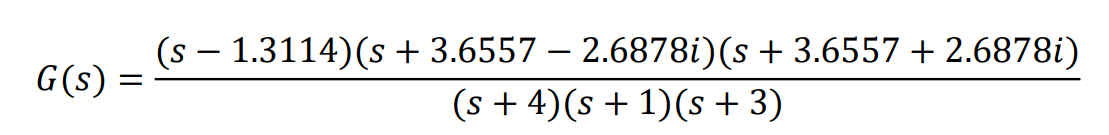

% 零极点模型的描述
k_1_1 = 1

k_1_1 = 1

z_1_1 = [1.3114 -3.6557+2.6878i -3.6557-2.6878i]

z_1_1 =    1.3114 + 0.0000i  -3.6557 + 2.6878i  -3.6557 - 2.6878i


p_1_1 = [-4 -1 -3]

p_1_1 =     -4    -1    -3



% 零极点模型的封装
sys_1_1 = zpk(z_1_1,p_1_1,k_1_1)

sys_1_1 =
 
  (s-1.311) (s^2 + 7.311s + 20.59)
  --------------------------------
         (s+4) (s+3) (s+1)
 
连续时间零点/极点/增益模型。
模型属性


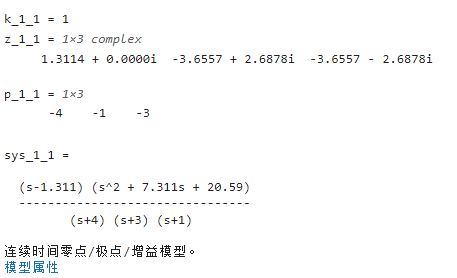

## 2. 已知一高阶单位负反馈系统的开环传递函数如下，使用Simulink中的传递函数模块建立系统。

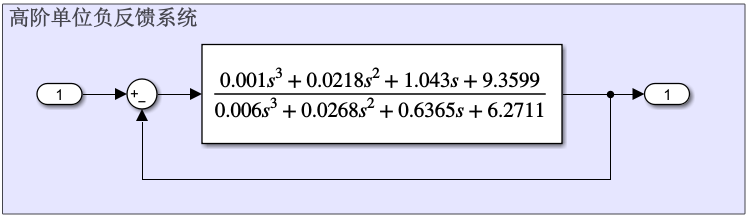

## 3. 已知两系统的传递函数模型，使用连接函数分别求两系统串联、并联时的传递函数。

% 定义传递函数 G1(s) 和 G2(s)的分子分母参数
k_3_1 = 6;
k_3_2 = 1;
z_3_1 = -2;
z_3_2 = -2.5;
p_3_1 = [-1 -3 -5];
p_3_2 = [-1 -4];

% 利用零极点模型封装传递函数 G1(s) 和 G2(s)
sys_3_1 = zpk(z_3_1,p_3_1,k_3_1)

sys_3_1 =
 
       6 (s+2)
  -----------------
  (s+1) (s+3) (s+5)
 
连续时间零点/极点/增益模型。
模型属性


sys_3_2 = zpk(z_3_2,p_3_2,k_3_2)

sys_3_2 =
 
    (s+2.5)
  -----------
  (s+1) (s+4)
 
连续时间零点/极点/增益模型。
模型属性



% 计算串联组合
G_series_3 = series(sys_3_1, sys_3_2);

% 计算并联组合
G_parallel_3 = parallel(sys_3_1, sys_3_2);

% 显示结果
disp('串联组合:');

串联组合:


G_series_3

G_series_3 =
 
       6 (s+2.5) (s+2)
  -------------------------
  (s+1)^2 (s+3) (s+4) (s+5)
 
连续时间零点/极点/增益模型。
模型属性



disp('并联组合:');

并联组合:


G_parallel_3

G_parallel_3 =
 
  (s+10.53) (s+3.879) (s+2.094) (s+1)
  -----------------------------------
       (s+1)^2 (s+3) (s+4) (s+5)
 
连续时间零点/极点/增益模型。
模型属性


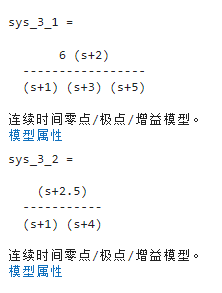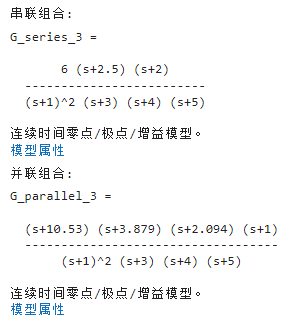

## 4. 已知某两输入两输出系统的状态方程，用MATLAB建立系统的状态空间模型，并求传递函数。考查ss2tf函数的使用方法：[b,a] = ss2tf(A,B,C,D,iu)。

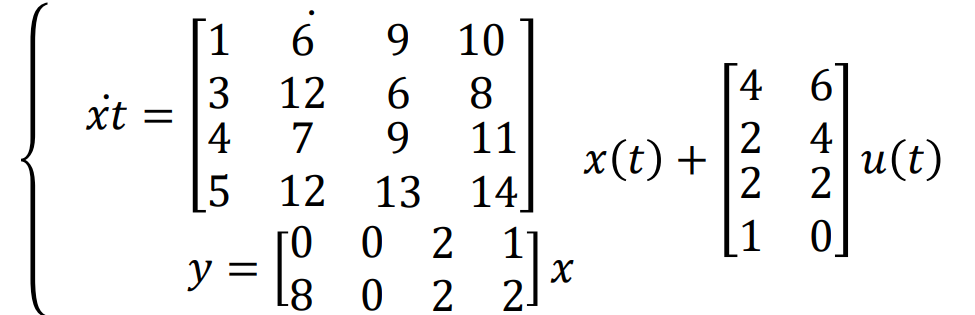

% 建立系统状态空间模型
A_4 = [1 6 9 10;3 12 6 9;4 7 9 11;5 12 13 14];
B_4 = [4 6;2 4;2 2;1 0];
C_4 = [0 0 2 1;8 0 2 2];
D_4 = [0 0;0 0];

% 分别求两个输入各自对应的两个输出传递函数
[num_4_1, den_4_1] = ss2tf(A_4,B_4,C_4,D_4,1);
sys_4_1_1 = tf(num_4_1(1,:),den_4_1)

sys_4_1_1 =
 
      5 s^3 + 22 s^2 - 165 s + 97
  -----------------------------------
  s^4 - 36 s^3 + 40 s^2 + 466 s + 408
 
连续时间传递函数。
模型属性


sys_4_1_2 = tf(num_4_1(2,:),den_4_1)

sys_4_1_2 =
 
   38 s^3 - 730 s^2 + 2362 s + 2976
  -----------------------------------
  s^4 - 36 s^3 + 40 s^2 + 466 s + 408
 
连续时间传递函数。
模型属性


[num_4_2, den_4_2] = ss2tf(A_4,B_4,C_4,D_4,2);
sys_4_2_1 = tf(num_4_2(1,:),den_4_2)

sys_4_2_1 =
 
     4 s^3 + 100 s^2 - 58 s + 386
  -----------------------------------
  s^4 - 36 s^3 + 40 s^2 + 466 s + 408
 
连续时间传递函数。
模型属性


sys_4_2_2 = tf(num_4_2(2,:),den_4_2)

sys_4_2_2 =
 
   52 s^3 - 1140 s^2 + 5324 s + 6240
  -----------------------------------
  s^4 - 36 s^3 + 40 s^2 + 466 s + 408
 
连续时间传递函数。
模型属性


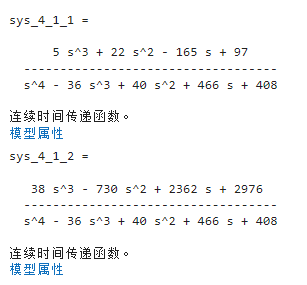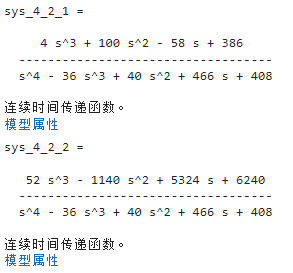

## 5.已知系统框图如下，求闭环系统传递函数。其中：G1(s)=2/((s+1)(s+8))；G2=1/s。

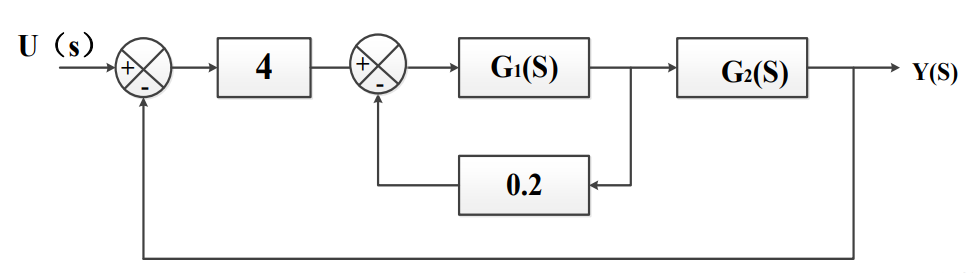

% 定义传递函数 G1(s) 和 G2(s)的分子分母参数
k_5_1 = 2;
k_5_2 = 1;
z_5_1 = [];
z_5_2 = [];
p_5_1 = [-1 -8];
p_5_2 = 0;

% 利用零极点模型封装传递函数 G1(s) 和 G2(s)
sys_5_1 = zpk(z_5_1,p_5_1,k_5_1);
sys_5_2 = zpk(z_5_2,p_5_2,k_5_2);

%定义
G_feedback_5_1 = feedback(sys_5_1,0.2,-1);
G_series_5_1 = series(4,G_feedback_5_1);
G_series_5_2 = series(G_series_5_1,sys_5_2);
G_5 = feedback(G_series_5_2,1,-1)

G_5 =
 
                  8
  ----------------------------------
  (s+8.083) (s^2 + 0.9167s + 0.9897)
 
连续时间零点/极点/增益模型。
模型属性


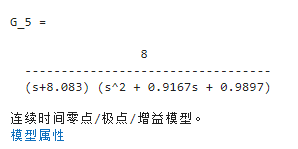

# 第九章 控制系统的稳定性分析

## 1. 已知单位负反馈系统的开环传递函数如下，绘制系统的单位负反馈零极点图并判断系统的稳定性。（可利用多项式乘法运算函数conv( )处理）

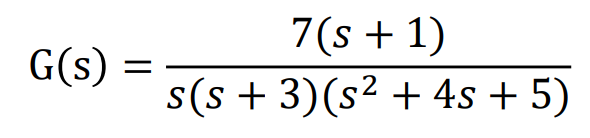

close
% 利用conv()定义传递函数分子分母系数
num_1_1 = 7*[1 1];
den_1_1 = conv([1,0],conv([1,3],[1,4,5]));
[num_1,den_1] = feedback(num_1_1,den_1_1,1,1,-1);

% 输出单位负反馈传递函数以验证是否正确
sys_1 = tf(num_1,den_1)

sys_1 =
 
              7 s + 7
  -------------------------------
  s^4 + 7 s^3 + 17 s^2 + 22 s + 7
 
连续时间传递函数。
模型属性


sys_val_1 = tf(num_1_1,den_1_1);
sys_val_2 = feedback(sys_val_1,1,-1)

sys_val_2 =
 
              7 s + 7
  -------------------------------
  s^4 + 7 s^3 + 17 s^2 + 22 s + 7
 
连续时间传递函数。
模型属性


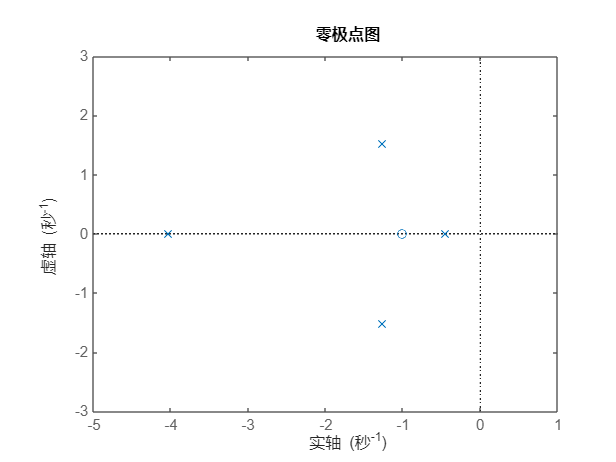


% 绘制连续系统的零极点图
hold off
pzmap(num_1,den_1)
axis([-5 1 -3 3])
hold off;


% 输出连续系统的零极点，判断系统稳定性
[p_1,z_1] = pzmap(sys_1);
i_1 = find(real(p_1)>0);  % 从极点中查找实部大于0的数
n_1 = length(i_1);  % 将极点中实部大于0的个数赋值于n
if(n_1>0) % 有极点位于S右半平面
    disp('系统不稳定'); % 显示系统不稳定
else % 极点全部位于S左半平面
    disp('系统稳定'); % 显示系统稳定
end

系统稳定


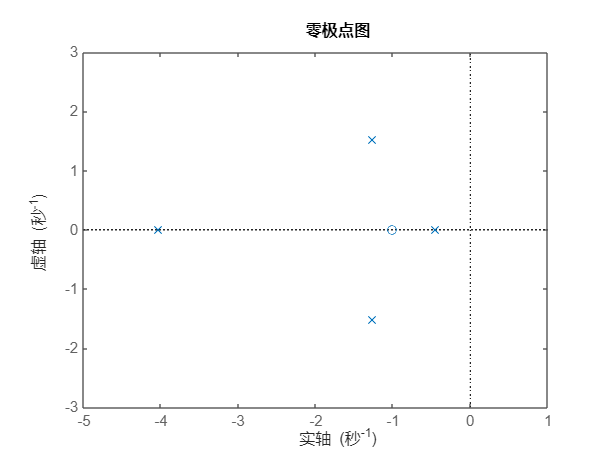

## 2. 计算以下系统的正弦波响应，已知正弦波的周期为4s，信号持续时间25s，表示采样周期0.1s，并使用Simulink实现仿真。

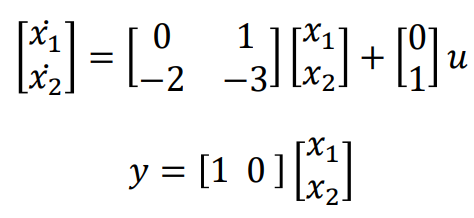

close
% 定义系统的传递函数
A_2 = [0 1;-2 -3];
B_2 = [0;1];
C_2 = [1 0];
D_2 = 0;
[num2_1,den2_1] = ss2tf(A_2,B_2,C_2,D_2)

num2_1 =      0     0     1


den2_1 =      1     3     2


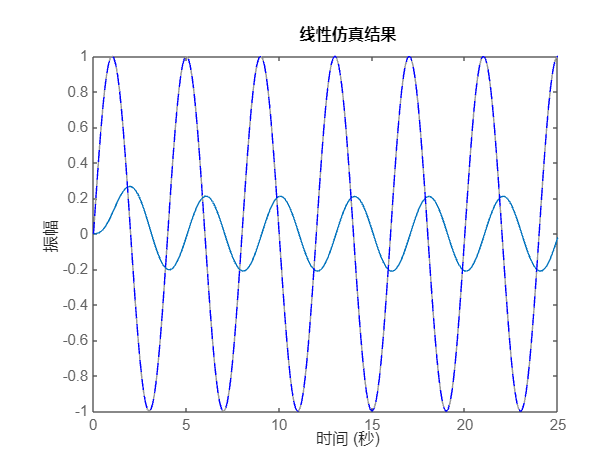


% 定义正弦波信号
tau_2 = 4;
Tf_2 = 25;
Ts_2 = 0.1;
[u_2,t_2] = gensig('sin',tau_2,Tf_2,Ts_2);

% 定义绘图窗口坐标轴范围
axis([0 30 -0.1 1.1]);

% 绘图
lsim(num2_1,den2_1,u_2,t_2);
hold on
plot(t_2,u_2,'b--');
hold off;

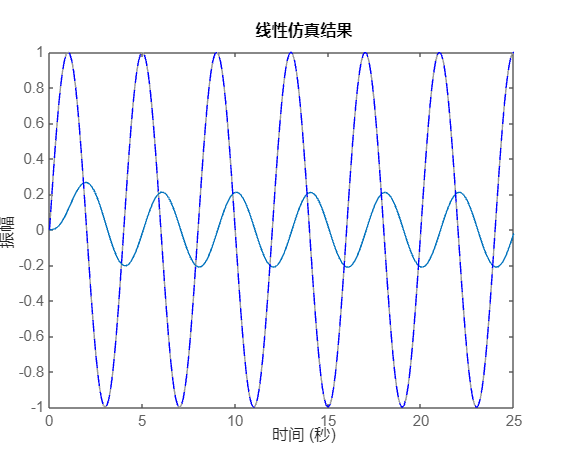

% 使用Simulink实现仿真

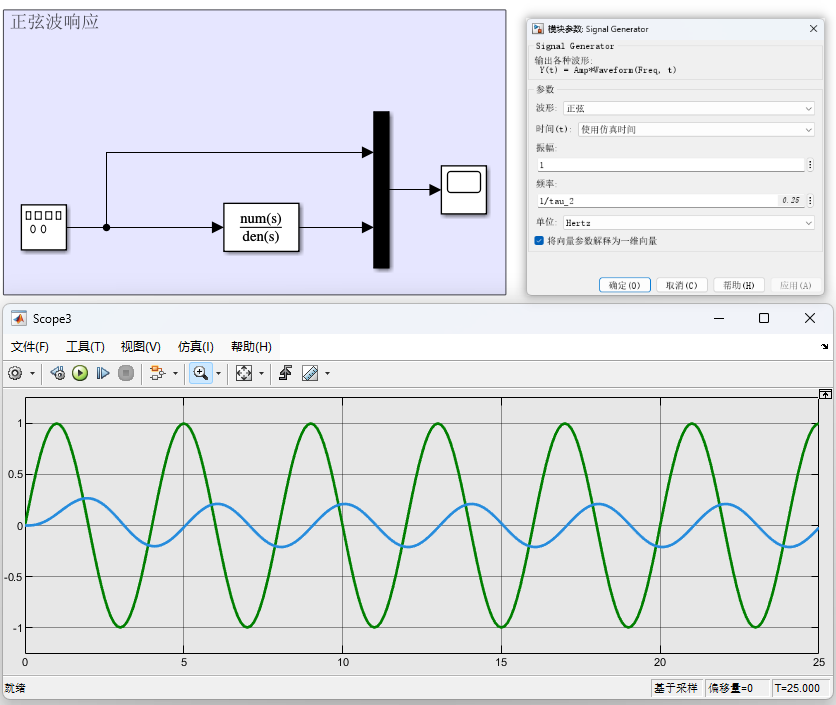

## 3. 已知单位负反馈系统，其开环传递函数如下，系统输入信号为下图的三角波，用两种方法求系统输出响应，并将输入和输出信号对比显示

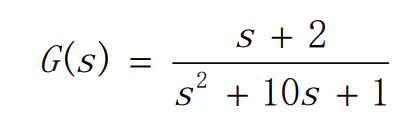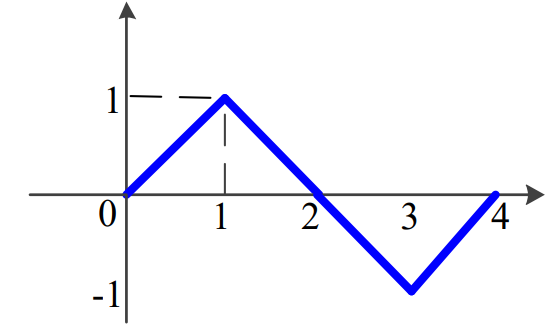

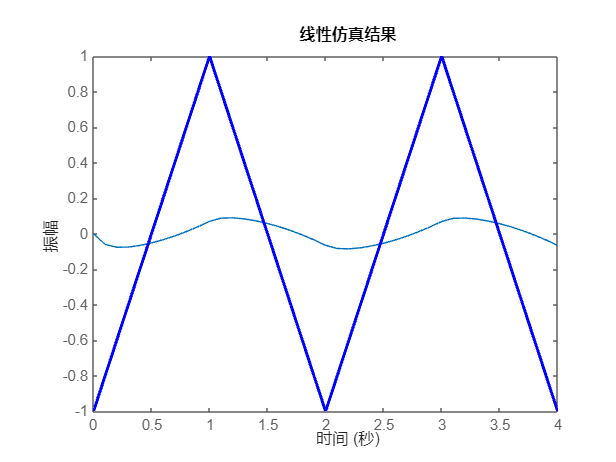

% 方法一：用自定义的三角波信号生产传递函数响应
close
% 定义系统的传递函数
num_3_1 = [1 2];
den_3_1 = [1 10 1];

% 定义系统的闭环传递函数
[num_3,den_3] = feedback(num_3_1,den_3_1,1,1,-1);

% 生成三角波信号
t_3 = 0:0.1:4; 
T_3 = 2; 
f_3 = 1/T_3; 
v_3 = 2 * abs(2 * (t_3 * f_3 - floor(t_3 * f_3 + 0.5))) - 1;

% 绘制信号
axis([0 4 -2 2]); % 设置轴范围
lsim(num_3,den_3,v_3,t_3);
hold on
plot(t_3, v_3, 'b', 'LineWidth', 2); % 使用蓝色线条，线宽为2
hold off

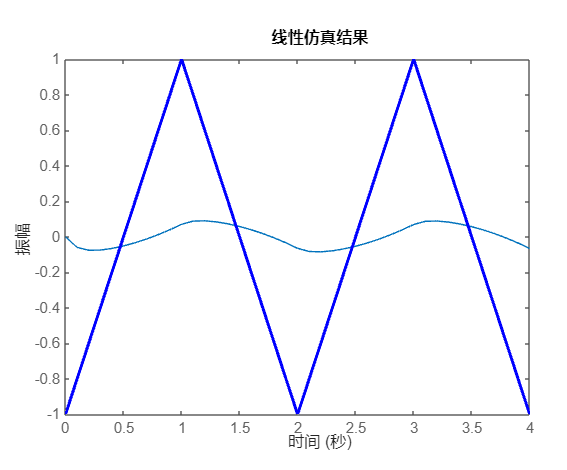

% 方法二：使用simulink实现仿真(Repeating Sequence模块)

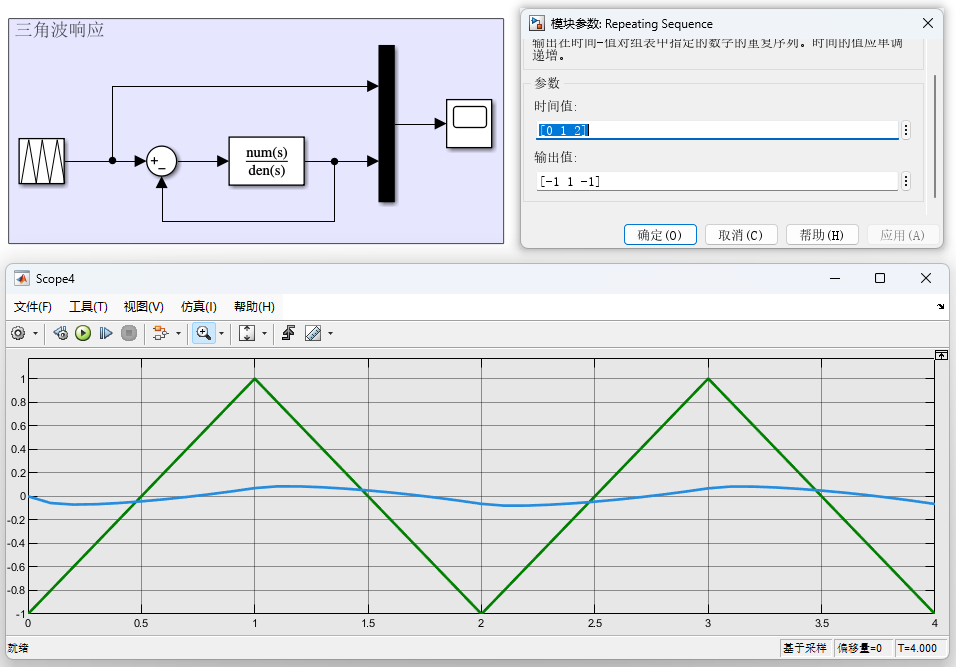

# 第10章 控制系统的时域分析

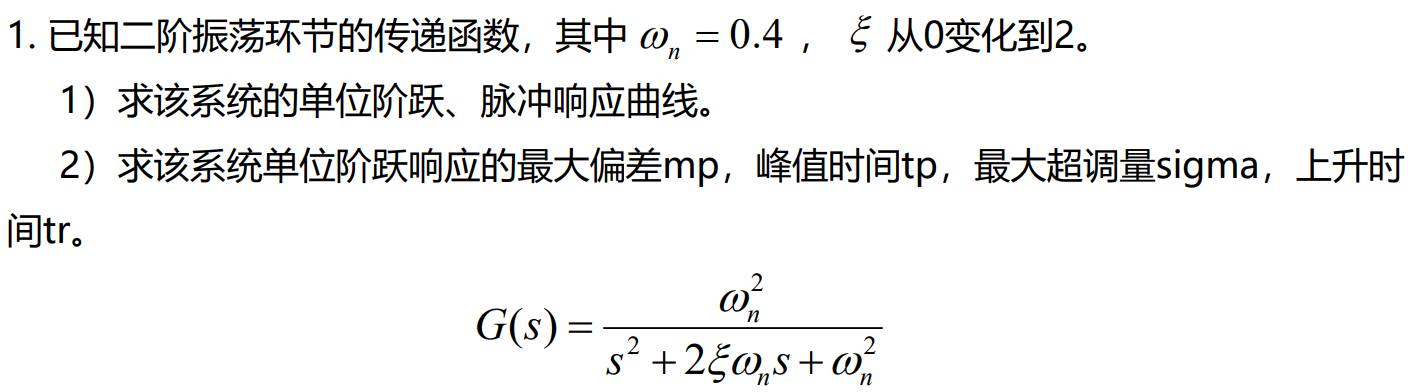

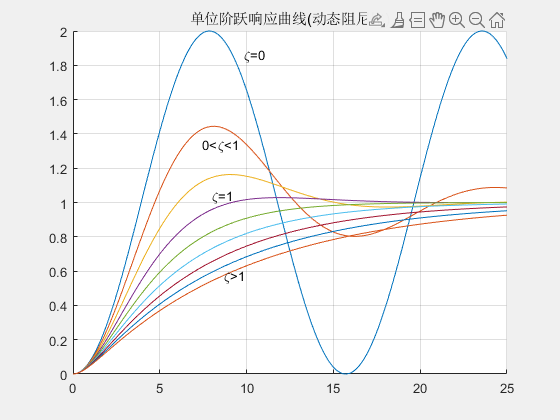

% 1.1) 绘制单位阶跃响应曲线
% 参数定义
close
clear
wn = 0.4; 
zetas = 0:0.25:2;  % 阻尼比变化
t = 0:0.1:25; %定义阶跃响应仿真时间
y = [];

% 遍历阻尼比绘制单位阶跃响应曲线
for zeta=zetas
    if zeta == 0
        y1 = 1-cos(wn*t);
    elseif(zeta>0 && zeta<1)
        wd = wn*sqrt(1-zeta^2);
        th = atan(sqrt(1-zeta^2)/zeta);
        y1 = 1-exp(-zeta*wn*t).*sin(wd*t+th)/sqrt(1-zeta^2);
    elseif zeta == 1
        y1 = 1-(1+wn*t).*exp(-wn*t);
    elseif zeta >1
        s1 = (-zeta+sqrt(zeta^2-1))*wn;
        s2 = (-zeta-sqrt(zeta^2-1))*wn;
        y1 = 1-0.5*wn*(-exp(s1*t)/s1+exp(s2*t)/s2)/sqrt(zeta^2-1);
    end
    y = [y;y1];
end

hold on
plot(t,y)
grid %在绘制的图形中添加栅格
gtext('\zeta=0') %设置图标
gtext('0<\zeta<1') %设置图标
gtext('\zeta=1') %设置图标
gtext('\zeta>1') %设置图标
title('单位阶跃响应曲线(动态阻尼比)')
hold off

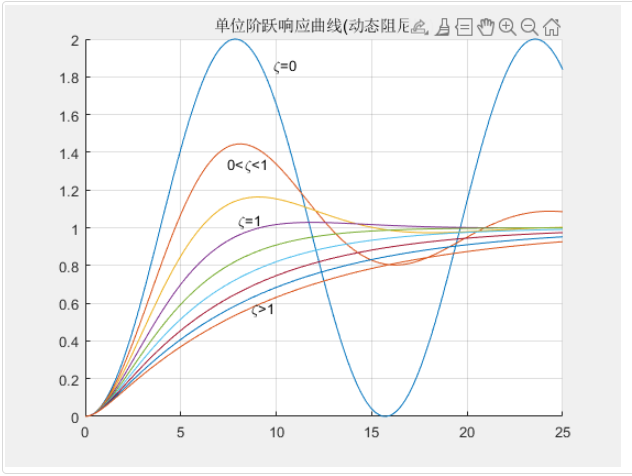

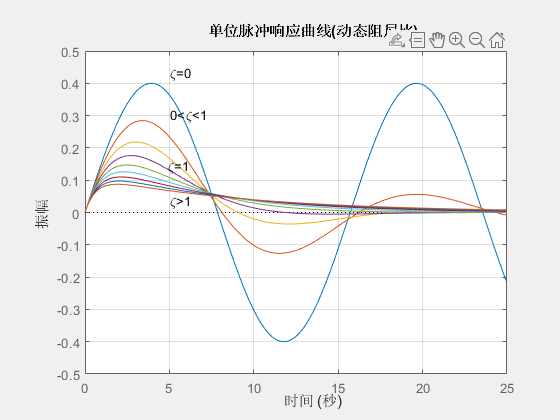

% 1.2) 使用impulse绘制单位脉冲响应曲线
close
clf;
hold on %图形绘制开关ON
for i=1:length(zetas)
    num_3=wn^2; %定义分子系数
    den_3=[1,2*wn*zetas(i), wn^2]; %对应分母系数
    axis([0 25 -1 1]); %设定x和y轴范围
    impulse(num_3,den_3,t) %绘制单位阶跃响应曲线
end
axis([0 25 -0.5 0.5]); %设定x和y轴范围
gtext('\zeta=0') %设置图标
gtext('0<\zeta<1') %设置图标
gtext('\zeta=1') %设置图标
gtext('\zeta>1') %设置图标
title('单位脉冲响应曲线(动态阻尼比)')
grid %绘制网格
hold off %图形绘制开关OFF

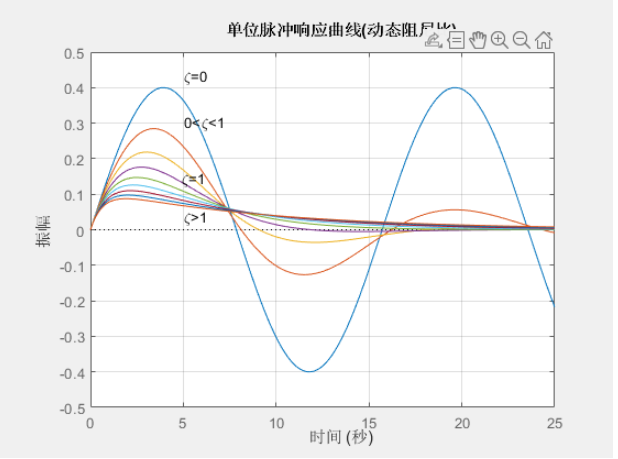

% 2) 时域分析
num_3 = wn^2; %定义传递函数分子系数
for i = 1:length(zetas)
    de = [1,2*zetas(i)*wn,wn^2]; %定义传递函数分母系数
    sys = tf(num_3,den_3); %建立传递函数模型
    t = 0:0.01:20; %响应时间
    [Y,T] = step(sys,t); %单位阶跃响应
    n = num2str(zetas(i));
    disp([newline,'zeta=',n]);
    [mp, tp, sigma,tr1]=steppa(Y,T) %调用计算动态指标的steppa函数
    disp('--------------');
end


zeta=0


mp = 0.8737

tp = 20

sigma = 0

tr1 = 13.6400

--------------



zeta=0.25


mp = 0.8737

tp = 20

sigma = 0

tr1 = 13.6400

--------------



zeta=0.5


mp = 0.8737

tp = 20

sigma = 0

tr1 = 13.6400

--------------



zeta=0.75


mp = 0.8737

tp = 20

sigma = 0

tr1 = 13.6400

--------------



zeta=1


mp = 0.8737

tp = 20

sigma = 0

tr1 = 13.6400

--------------



zeta=1.25


mp = 0.8737

tp = 20

sigma = 0

tr1 = 13.6400

--------------



zeta=1.5


mp = 0.8737

tp = 20

sigma = 0

tr1 = 13.6400

--------------



zeta=1.75


mp = 0.8737

tp = 20

sigma = 0

tr1 = 13.6400

--------------



zeta=2


mp = 0.8737

tp = 20

sigma = 0

tr1 = 13.6400

--------------


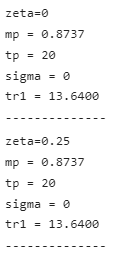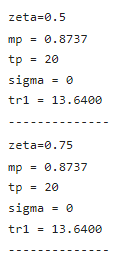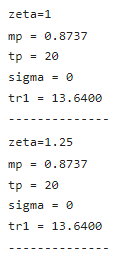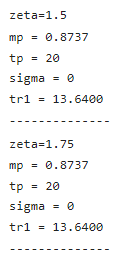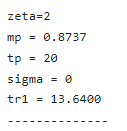

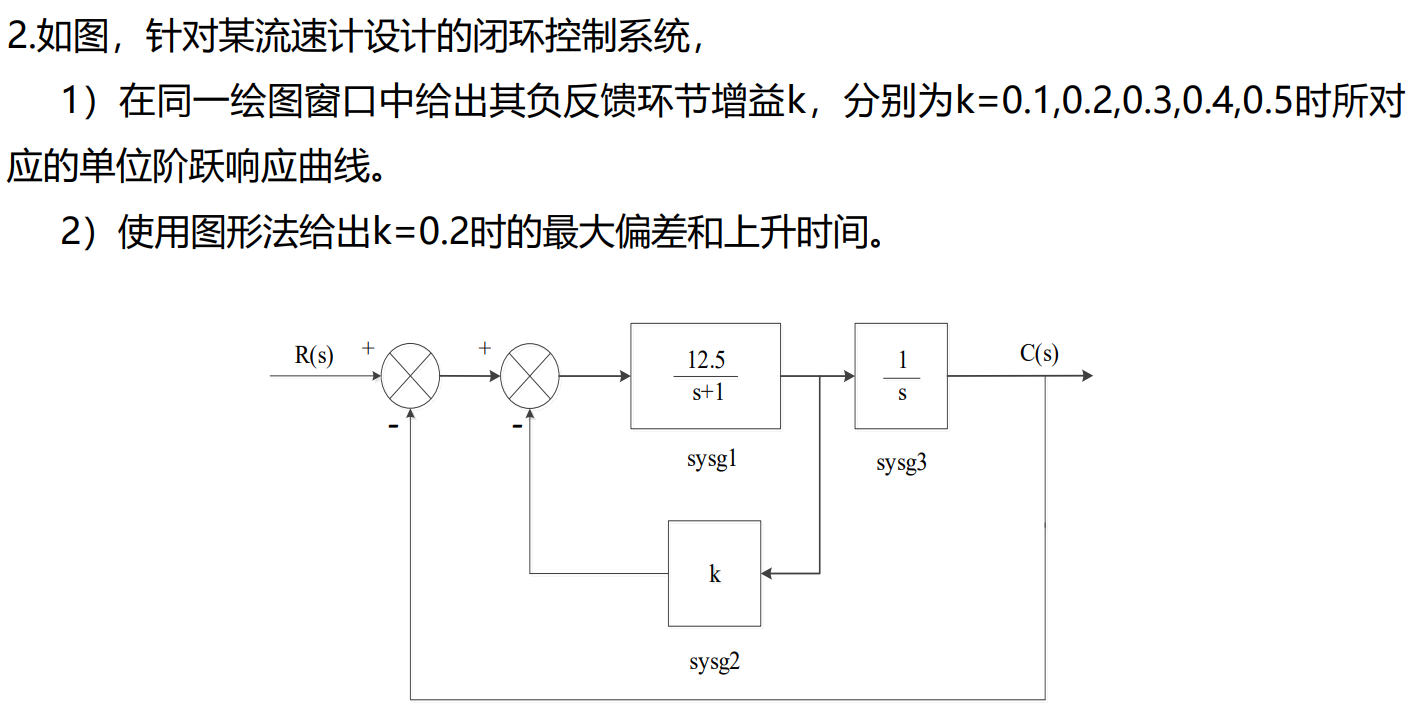

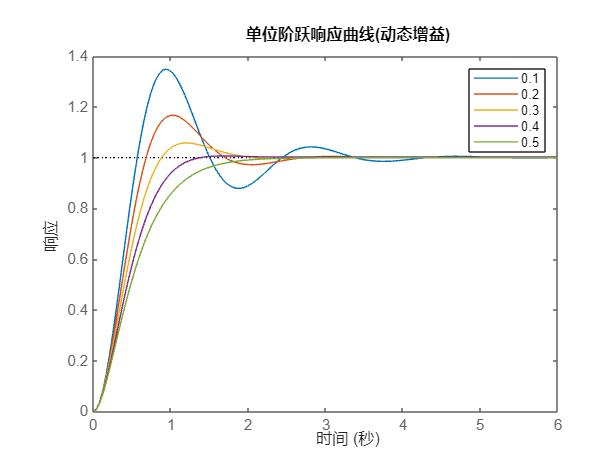

% 1) 不同增益k对应的单位阶跃响应曲线
% 定义系统的传递函数
close
clear
sysg1 = tf(12.5, [1 1]);
sysg3 = tf(1, [1 0]);

% k值数组
k_s = 0.1:0.1:0.5;


% 对每个k值计算和绘制单位阶跃响应
for k = k_s
    sysg2 = tf(k);
    
    % 根据图中的控制系统计算不同增益下的闭环传递函数
    sys1 = feedback(sysg1,sysg2,-1); % 定义内部反馈系统sys1
    sys2 = series(sys1, sysg3); % sysg3和内部反馈系统sys1串联
    sys = feedback(sys2,1,-1); % 定义整体系统传递函数
   
    % 绘制单位阶跃响应
    step(sys);
    hold on; % 保持图形，以便在同一图形上绘制所有曲线
end

% 添加图例
legend(arrayfun(@num2str, k_s, 'UniformOutput', false));
title('单位阶跃响应曲线(动态增益)');
xlabel('时间');
ylabel('响应');

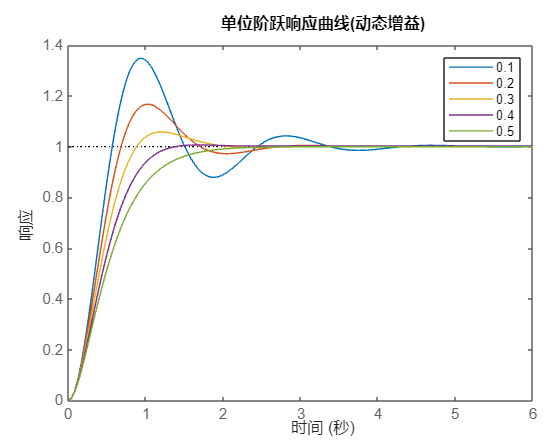

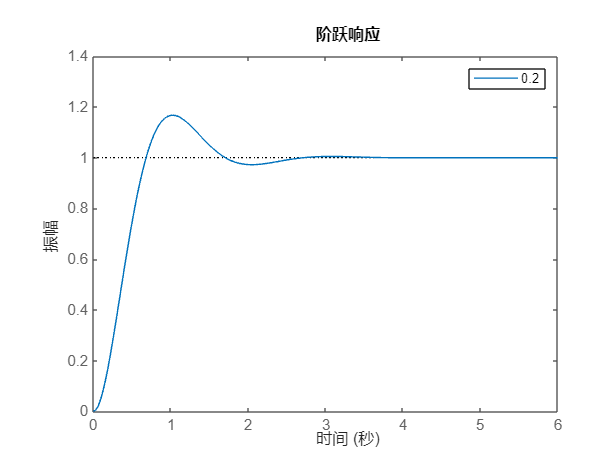

% 2) 图形法计算最大偏差和上升时间
close
clear
sysg1 = tf(12.5, [1 1]);
sysg3 = tf(1, [1 0]);
k = 0.2;
sysg2 = tf(k);
sys1 = feedback(sysg1,sysg2,-1); % 定义内部反馈系统sys1
sys2 = series(sys1, sysg3); % sysg3和内部反馈系统sys1串联
sys = feedback(sys2,1,-1); % 定义整体系统传递函数


% 绘制单位阶跃响应
figure
step(sys)
axis([0 6 0 1.4]); %设定x和y轴范围
legend('0.2');

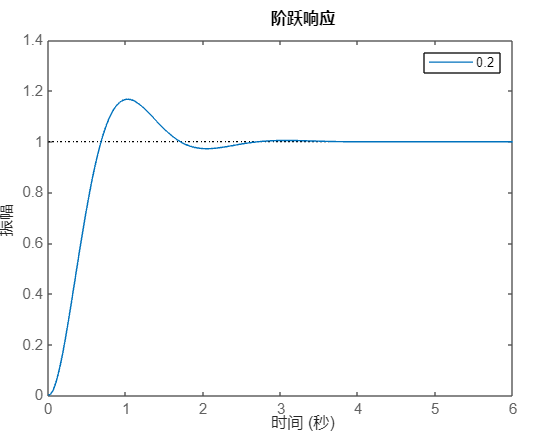

% 利用图形法得到下图
% k=0.2时最大偏差为1.17，上升时间为0.461s

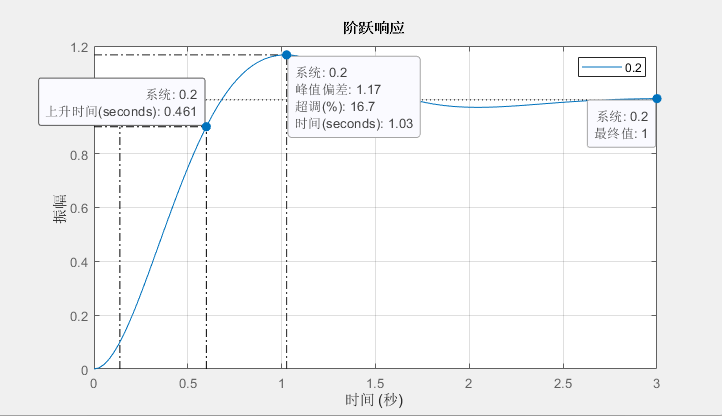

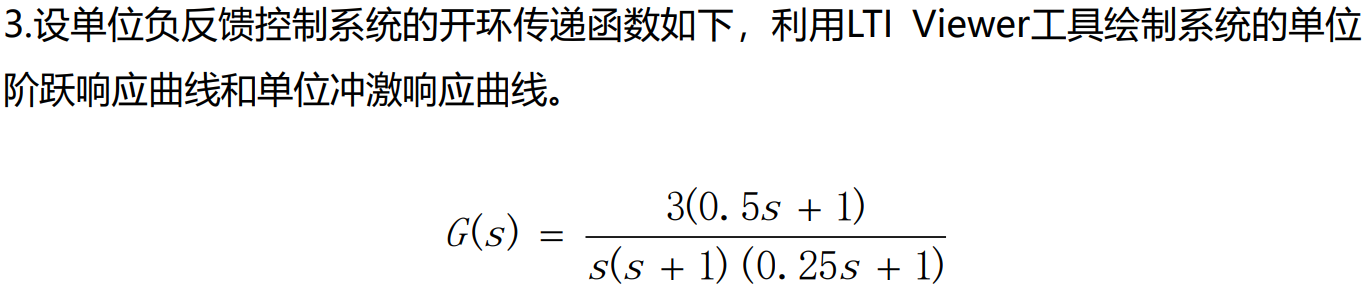

% 3）利用LTI Viewer工具绘制单位阶跃响应曲线和单位冲激响应曲线
% 定义系统传递函数
num_3_1 = [0.5 1];
num_3 = 3*num_3_1;
den_3_1 = conv([1,0],[1,1]);
den_3 = conv([1,0],conv([1,1],[0.25,1]));
sys_3 = tf(num_3,den_3)

sys_3 =
 
         1.5 s + 3
  -----------------------
  0.25 s^3 + 1.25 s^2 + s
 
连续时间传递函数。
模型属性


sys = feedback(sys_3,1,-1)

sys =
 
             1.5 s + 3
  -------------------------------
  0.25 s^3 + 1.25 s^2 + 2.5 s + 3
 
连续时间传递函数。
模型属性


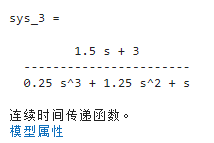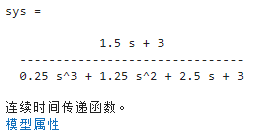

% 利用LTI Viewer工具绘制单位阶跃响应曲线和单位冲激响应曲线如下图所示：